# ECE 101 - Specialized Plotting

Michael Dekoski

4-28-23

clc
clear

## Plotting Non-functional trace

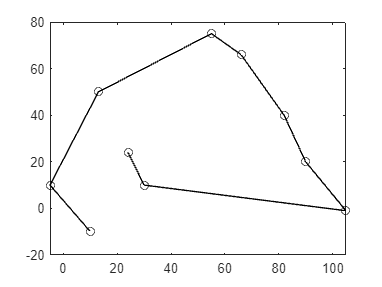

truckX = [24 30 105 90 82 66 55 13 -5 10];
truckY = [24 10 -1 20 40 66 75 50 10 -10];
plot(truckX, truckY, 'o-k')

## Logarithmic Scales X, Y, Both

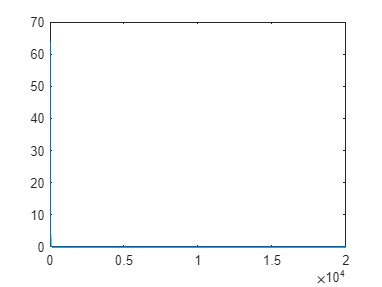

logTimes = linspace(20,20000,1000);
logTestMag = 2.^(-0.2*logTimes+10);

plot(logTimes, logTestMag)

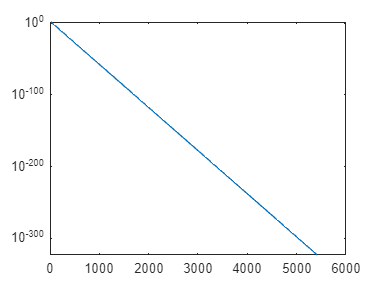


semilogy(logTimes, logTestMag)

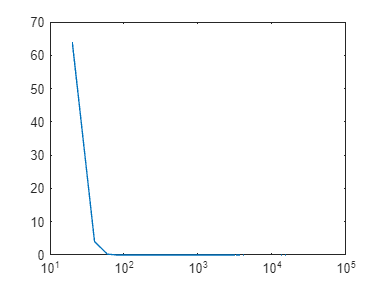

semilogx(logTimes, logTestMag)

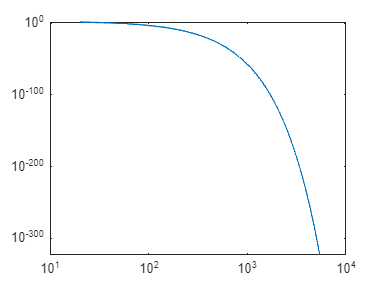


loglog(logTimes, logTestMag)

## Error Bars

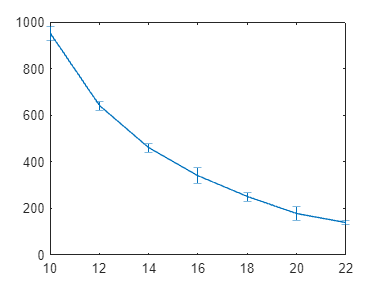

errBarsX = [10:2:22];
errMagAvg = [950 640 460 340 250 180 140];
errSizeBars = [30 20 18 35 20 30 10];

errorbar(errBarsX, errMagAvg, errSizeBars)

## Pie Charts

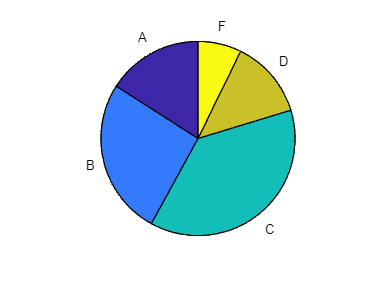

studentGrade = [11 18 26 9 5];
gradePirLabels = {'A', 'B', 'C', 'D', 'F'};

pie(studentGrade, gradePirLabels)

## Histogram

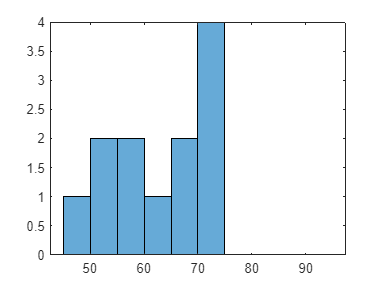

histVal = [58 72 73 53 50 48 56 73 73 66 69 63];
histBin = [45:5:95];

histogram(histVal, histBin)

## Polar Plots

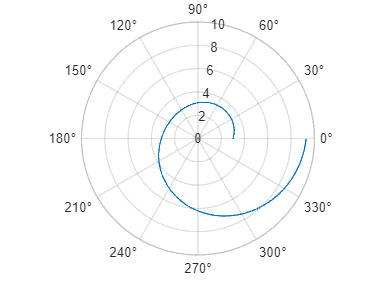

polarAngles = linspace(0, 2*pi, 200);
polarMag = 3*cos(0.5*polarAngles).^2+polarAngles;

polarplot(polarAngles, polarMag)

## Using User defined function

var1 = -27;
var2 = 109;
[o1, o2] = loopback(var1, var2)

o1 = -27

o2 = 109

## Logicals

Zero == False, Otherwise == True

bool1 = true;
bool2 = false;
andLogicOut = bool1 & bool2;
orLogicOit = bool1 | bool2;

## User defined function

function [output1, output2] = loopback(input1, input2)
    % This is a loopback function
    % returns what was put in
    output1 = input1;
    output2 = input2;
end